format long eng;
kbr1b_x = importdata("KBR1B_2020-09-17_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-17_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-17_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-17_D_04.txt");
lri1b_x = importdata("LRI1B_2020-09-17_Y_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
% eqb1 = kbr1b_x(:, 2) - 
for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
eqa(:, 1: 3) = -eqa(:, 1: 3);
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 10822: 11421
% 10822: 11421
% 8636: 9235

% 8636: 9235

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);

% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);
lsqr(diff3_eqa(4036: 4036+600, [2 3 5 6]), diff3_eqb(4036: 4036+600) - diff3_eqa(4036: 4036+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.98。


ans =    -90.0558257362401e-006
    486.125914432574e-006
   -7.22759291213943e-003
    16.2887780730987e-003


lsqr(diff2_eqa(4036: 4036+600, [2 3 4 5 6]), diff2_eqb(4036: 4036+600) - 1.444 * diff2_eqa(4036: 4036+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.98。


ans =     245.122948588327e-006
    646.146994733951e-006
   -11.6332748880261e-006
   -14.6810421793426e-003
    69.3616263033407e-003


lsqr(diff3_eqa(6354: 6354+600, [2 3 4 5 6]), diff3_eqb(6354: 6354+600) - 1.444 * diff3_eqa(6354: 6354+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.99。


ans =    -6.20629475030042e-003
   -216.398157492183e-006
   -2.76082003808549e-006
    14.0458270563531e-003
   -8.94172170459704e-003


lsqr(diff2_eqa(6354: 6354+600, [2 3 5 6]), diff2_eqb(6354: 6354+600) - diff2_eqa(6354: 6354+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.98。


ans =     52.6407587707645e-003
   -235.890795386939e-006
   -1.71696912361505e-003
   -29.2180313894267e-003


lsqr(diff3_eqa(8624: 8624+600, [2 3 4 5 6]), diff3_eqb(8624: 8624+600) - 1.444 * diff3_eqa(8624: 8624+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.97。


ans =    -783.678601304884e-006
   -2.35567677942187e-003
   -33.7683090802271e-006
    25.8883833819906e-003
    8.29416732597212e-003


lsqr(diff2_eqa(8624: 8624+600, [2 3 4 5 6]), diff2_eqb(8624: 8624+600) - 1.444 * diff2_eqa(8624: 8624+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.98。


ans =    -783.198602237070e-006
   -13.1411594606005e-003
   -33.8414745969711e-006
   -31.7139062225077e-003
    18.4488067598521e-003


lsqr(diff3_eqa(10822: 10822+600, [2 3 5 6]), diff3_eqb(10822: 10822+600) - diff3_eqa(10822: 10822+600, [1 4]) * [1.444; 1.444])

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.99。


ans =    -231.573836146280e-006
    7.92541328993929e-003
   -18.2747401593804e-003
   -35.3069090549136e-003


lsqr(diff2_eqa(10822: 10822+600, [2 3 5 6]), diff2_eqb(10822: 10822+600) - diff2_eqa(10822: 10822+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.99。


ans =    -241.030766192609e-006
    2.61006430520726e-003
    13.7273843962798e-003
   -27.2525450135038e-003


solver_spectral(diff2_eqa(6354: 6354+600, :), diff2_eqb(6354: 6354+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0089。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0089。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.0089。


FFT_model_mat_at_freq_signal =     9.67640440178954e-006   -280.402228231674e-006
    4.97956723652825e-006    343.417108636272e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.028。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.028。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.028。


FFT_data_vec_at_freq_signal =     14.0460617746474e-006
    6.95754183344805e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 5.1e-11。


ans =    -261.530797832096e-006


solver_spectral(diff3_eqa(10822: 11421, :), diff3_eqb(10822: 11421), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。


FFT_model_mat_at_freq_signal =     1.19470760406592e-006   -34.5548806545137e-006
    1.28060706723836e-006    2.67493037656833e-006


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。


FFT_data_vec_at_freq_signal =     1.71703785675031e-006
    1.80108379317103e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 8.9e-12。


ans =     234.986299100884e-006


solver_spectral(diff3_eqa(4036: 4036+600, :), diff3_eqb(4036: 4036+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。


FFT_model_mat_at_freq_signal =     1.25861462288486e-006   -35.4686999729628e-006
    1.23018088773855e-006    1.36543513330137e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。


FFT_data_vec_at_freq_signal =     1.83919137918748e-006
    1.72326457711116e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.4e-11。


ans =    -613.269270041620e-006


solver_spectral(diff3_eqa(8624: 8624+600, :), diff3_eqb(8624: 8624+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.99。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.99。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.99。


FFT_model_mat_at_freq_signal =     1.25757555936421e-006   -61.7940054709551e-009
    1.28420591432811e-006    21.4294659101336e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.05。


FFT_data_vec_at_freq_signal =     1.84333333818377e-006
    1.79402430402272e-006


lsqr 在解的 迭代 2 处收敛，并且相对残差为 4.1e-11。


ans =    -443.315338649180e-003


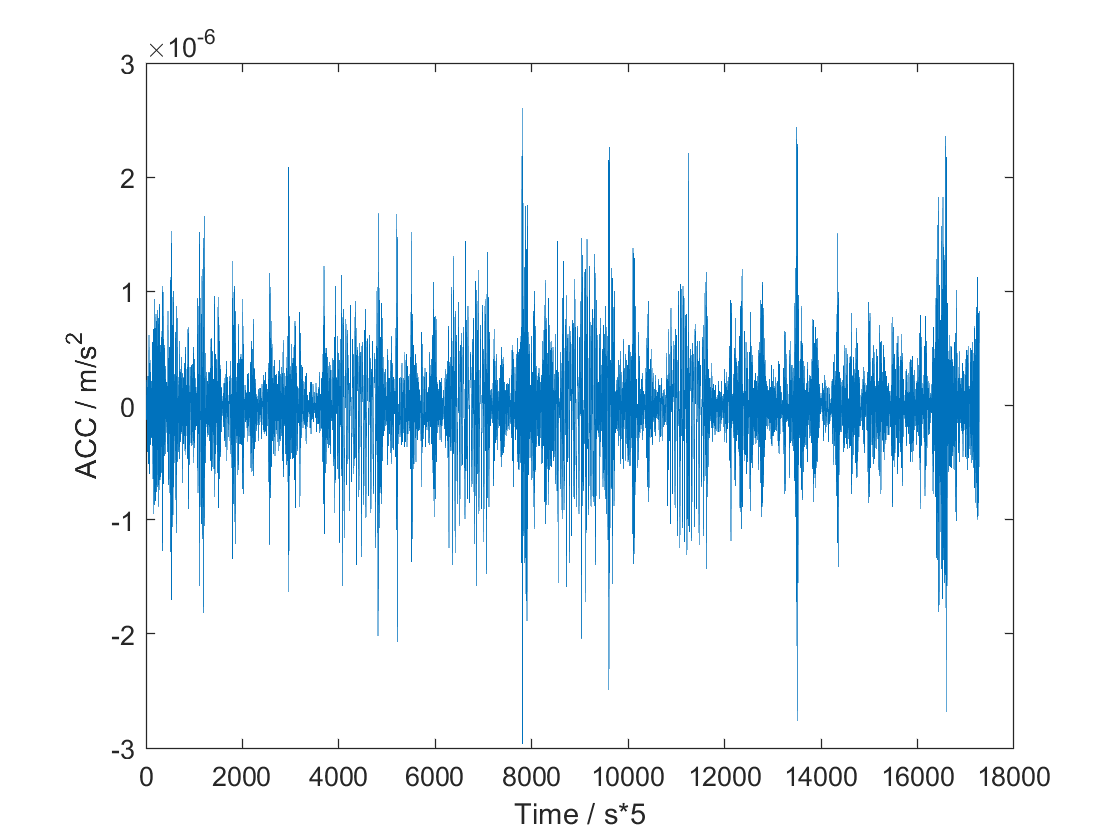

acc_grav = importdata("..//..//temp//acc_grav_calibra2.txt");
acc_grav = acc_grav(1: 86400, :);
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-17_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-17_D_04.txt");
gni_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni_b = importdata("GNI1B_2020-09-17_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-17_Y_04.txt");
acc_a = importdata("ACT1B_2020-09-17_C_04.txt");
acc_b = importdata("ACT1B_2020-09-17_D_04.txt");
acc_nongrav = [acc_a.data(:, 1) - mean(acc_a.data(:, 1)), acc_a.data(:, 2) - mean(acc_a.data(:, 2)), acc_a.data(:, 3) - mean(acc_a.data(:, 3)), acc_b.data(:, 1) - mean(acc_b.data(:, 1)), acc_b.data(:, 2) - mean(acc_b.data(:, 2)), acc_b.data(:, 3) - mean(acc_b.data(:, 3))];
acc_nongrav_gcrs = zeros(size(acc_nongrav));
for i = 1: length(acc_nongrav)
    rotm_a = quat2rotm(sca_c.data(i, 2: 5));
    rotm_b = quat2rotm(sca_d.data(i, 2: 5));
    acc_nongrav_gcrs(i, 1: 3) = rotm_a * acc_nongrav(i, 1: 3)';
    acc_nongrav_gcrs(i, 4: 6) = rotm_b * acc_nongrav(i, 4: 6)';
end
acc_nongrav_rela = [acc_nongrav_gcrs(:, 1) - acc_nongrav_gcrs(:, 4), acc_nongrav_gcrs(:, 2) - acc_nongrav_gcrs(:, 5), acc_nongrav_gcrs(:, 3) - acc_nongrav_gcrs(:, 6)];

range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :)) + dot(acc_nongrav_rela(i, :), los_i(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res); xlabel("Time / s*5"); ylabel("ACC / m/s^2")

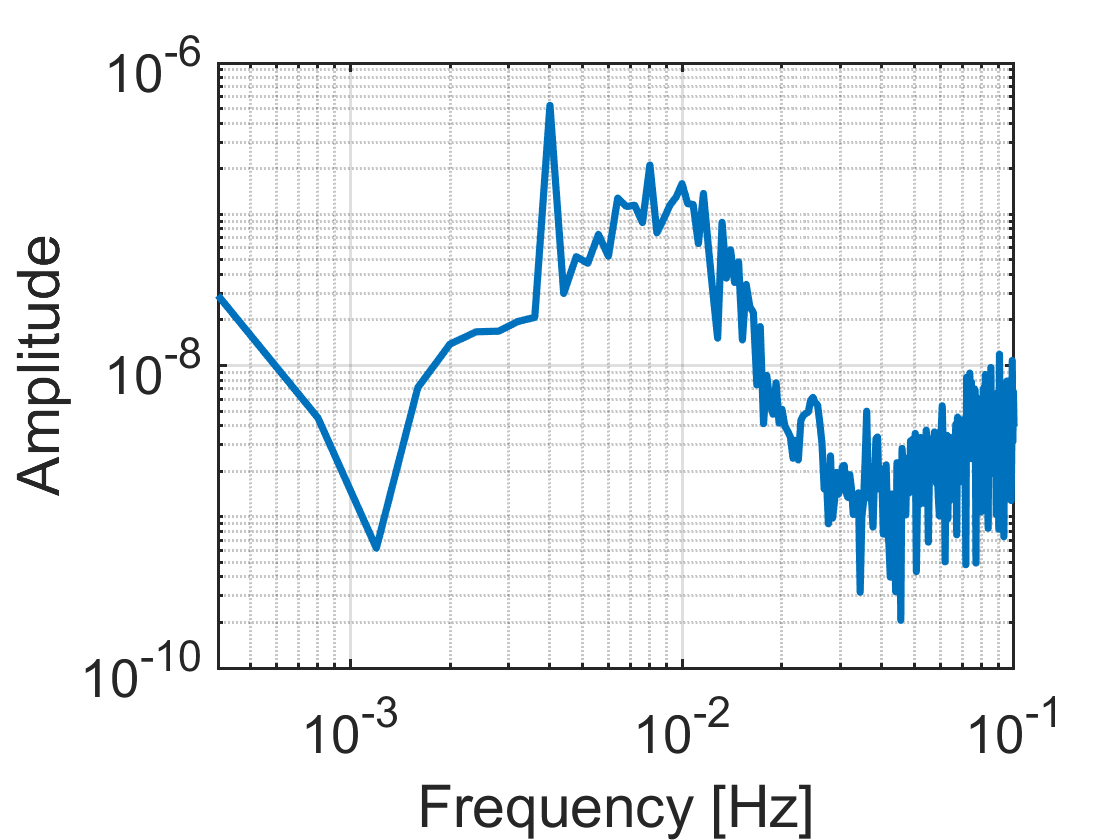

figure; fft_plot(range_acc_res(4036: 4036+499), 0.2)

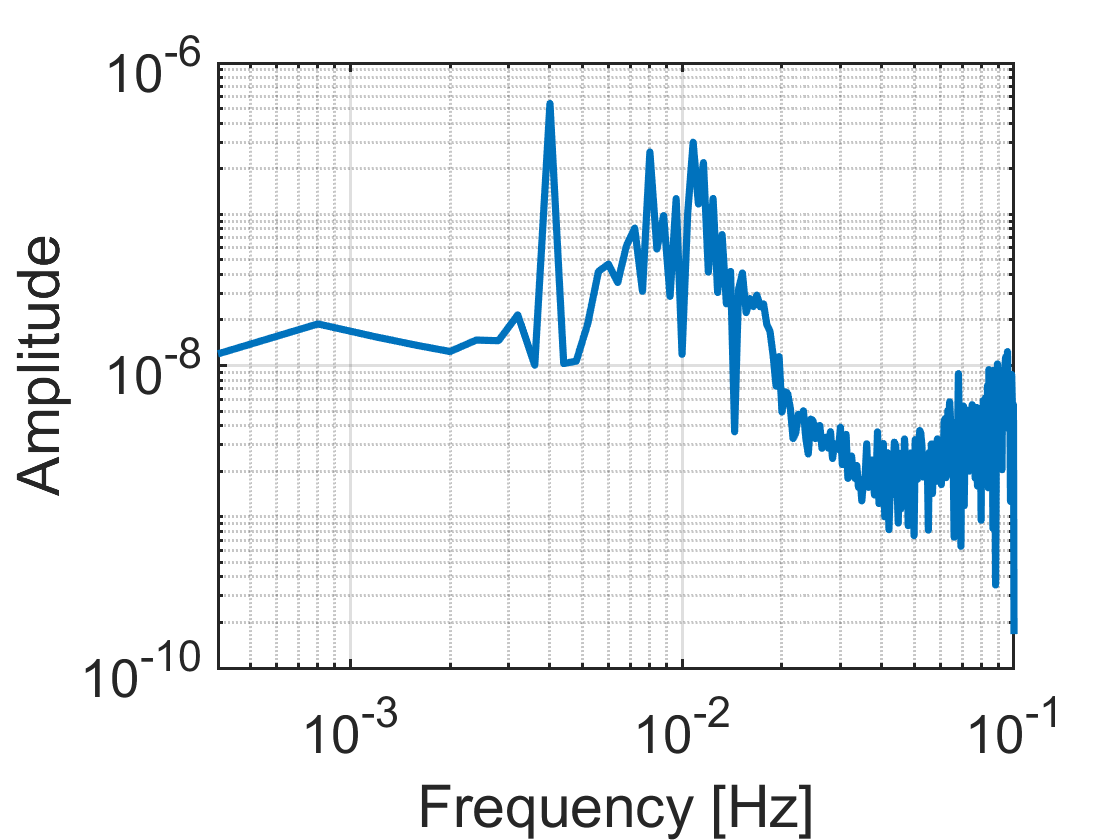

figure; fft_plot(range_acc_res(6354: 6354+499), 0.2)

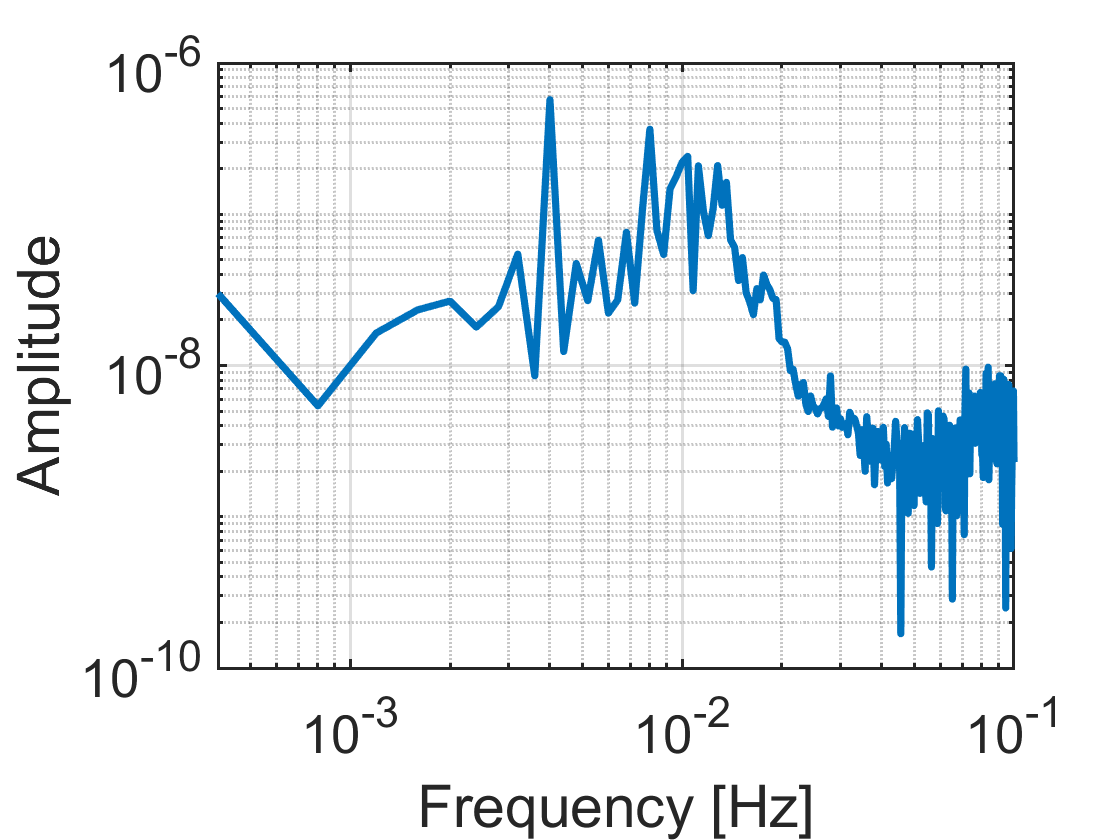

figure; fft_plot(range_acc_res(8624: 8624+499), 0.2)

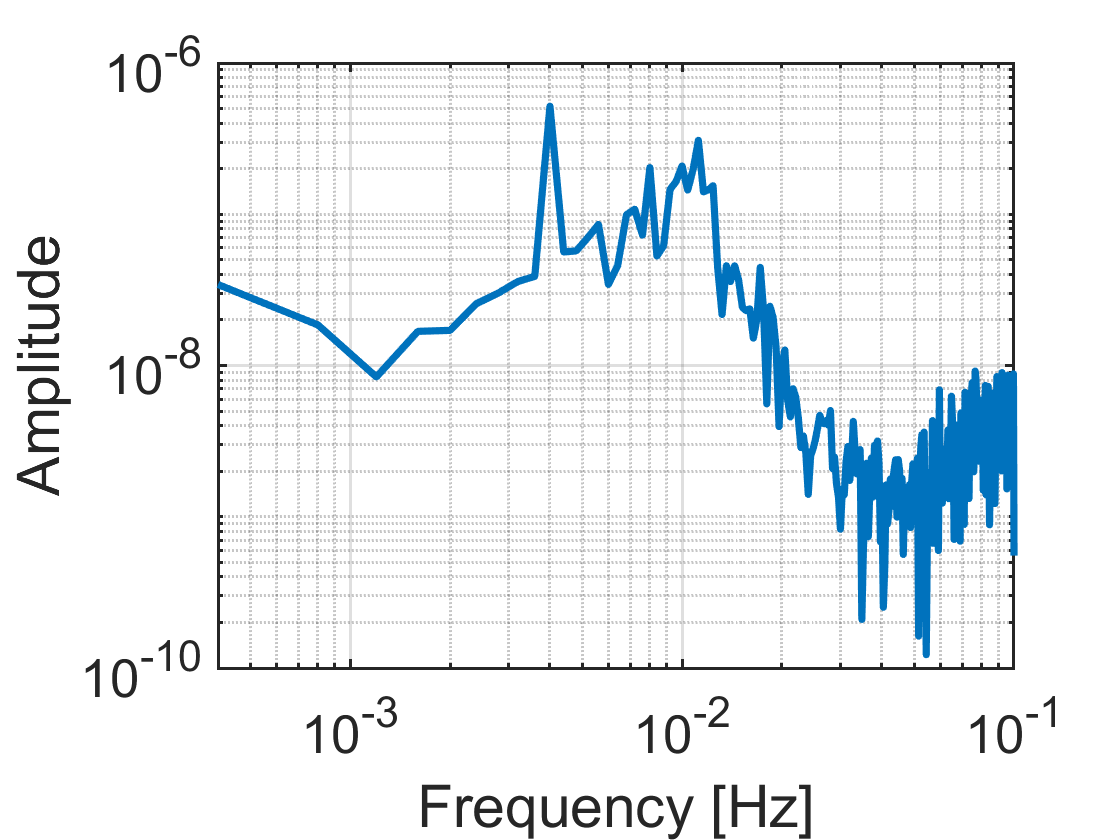

figure; fft_plot(range_acc_res(10822: 10822+499), 0.2)

a1 = spectral_component(filter_pdfree(Num, range_acc_res(4036: 4036+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.55。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.55。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.55。


a1 =     558.287454993767e-009
    210.481952239421e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(4036: 4036+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0087。


a2 =     371.081886420422e-009
    182.785903508326e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(4036: 4036+600, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0092。


a3 =     10.6840528435775e-006
    6.44840416611764e-009


q1 = -(a1(1) - 1.4443985 * a2(1)) / a3(1)

q1 =    -2.08697347321181e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(6354: 6354+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。


a1 =     552.633251949356e-009
    219.226117967447e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(6354: 6354+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.0087。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.0087。


a2 =     370.954241267125e-009
    182.803497085613e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(6354: 6354+600, 3)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0093。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0093。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0093。


a3 =     10.6926949088098e-006
    9.69560721714895e-009


q2 = (a1(1) - 1.4443985 * a2(1)) / a3(1)

q2 =     1.57373818649014e-003


q2 = (5.4018e-7 - 1.4443985 * a2(1)) / a3(1)

q2 =     409.087735358724e-006


q5 = (a1(1) - 1.4443985 * a2(1)) / a3(1)

q5 =     1.57373818649014e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(8624: 8624+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.72。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.72。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.72。


a1 =     567.696545331950e-009
    299.744339362275e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8624: 8624+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.009。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.009。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.009。


a2 =     370.701141584644e-009
    182.804468358160e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8624: 8624+600, 2)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。


a3 =     1.10421505789693e-006
    1.64012195578925e-009


q3 = -(a1(1) - 1.4443985 * a2(1)) / a3(1)

q3 =    -29.2120382240007e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(10822: 10822+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.7。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.7。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.7。


a1 =     544.702799667990e-009
    219.784543944920e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 10822+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0094。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0094。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.0094。


a2 =     371.014552226594e-009
    182.907071080433e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 10822+600, 2)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。


a3 =     1.09851863029236e-006
    5.21005961365730e-009


q4 = (a1(1) - 1.4443985 * a2(1)) / a3(1)

q4 =     8.01983390248074e-003


(q4 + q3) / 2.0

ans =    -10.5961021607600e-003


q6 = (a1(1) - 1.4443985 * a2(1) - 17*0.8e-6*(2*pi/250.0)^2) / a3(1)

q6 =     199.753811147304e-006
